load Scale_Measurements.mat

weight = ScaleMeasurements.weightg;
weightln = log(weight);
sensValue =ScaleMeasurements.sensValue;
sensLn = log(sensValue);

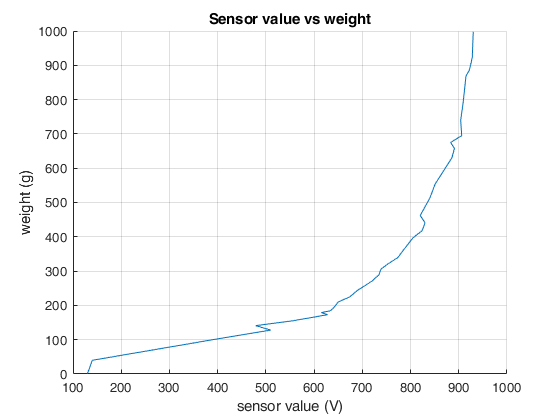


figure(1) 
hold on;
plot(sensValue,weight)
grid on;
ylabel({'weight (g)'});
xlabel({'sensor value (V)'});
title({'Sensor value vs weight'});
hold off;


input = table(sensValue,weightln);
regModel = fitlm(input,"weightln ~ sensValue");

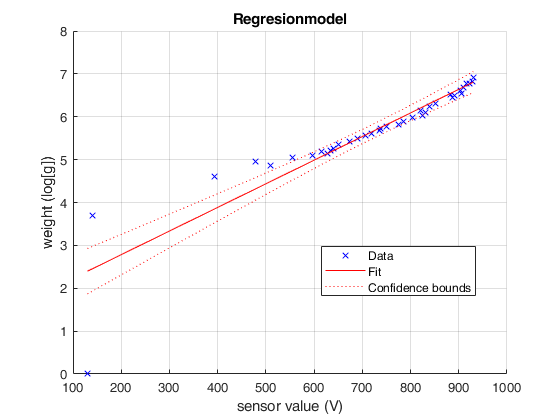


figure(2)
hold on;
plot(regModel)
grid on;
ylabel({'weight (log[g])'});
xlabel({'sensor value (V)'});
title({'Regresionmodel'});
hold off;

regModel.Coefficients

ans = 2×4 table
                   Estimate         SE        tStat       pValue  
                   _________    __________    ______    __________

    (Intercept)       1.6814        0.3127    5.3772    5.1168e-06
    sensValue      0.0055105    0.00041993    13.122    4.4589e-15
